# Step 1: Read Image

Read in the radar range doppler image and display to screen.

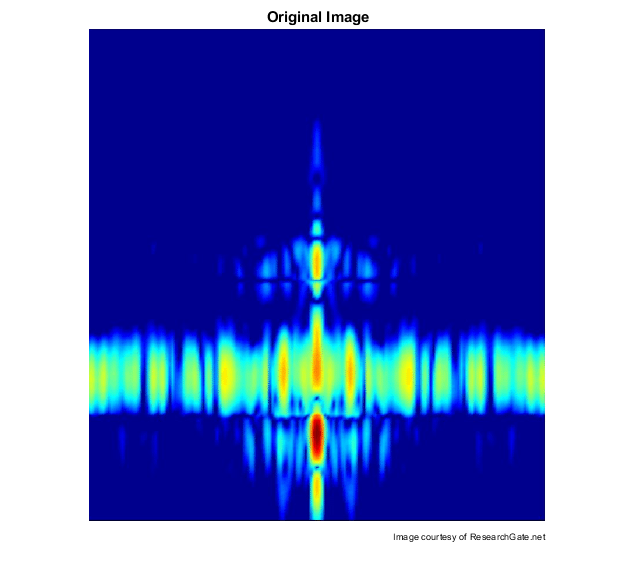

I = imread('test.png');
imshow(I)
title('Original Image');
text(size(I,2),size(I,1)+15, ...
    'Image courtesy of ResearchGate.net', ...
    'FontSize',7,'HorizontalAlignment','right');

## Step 2: Convert to Grayscale Image

Convert image to grayscale and display to screen.

Note: This step is important for the Sobel filter to work correctly.

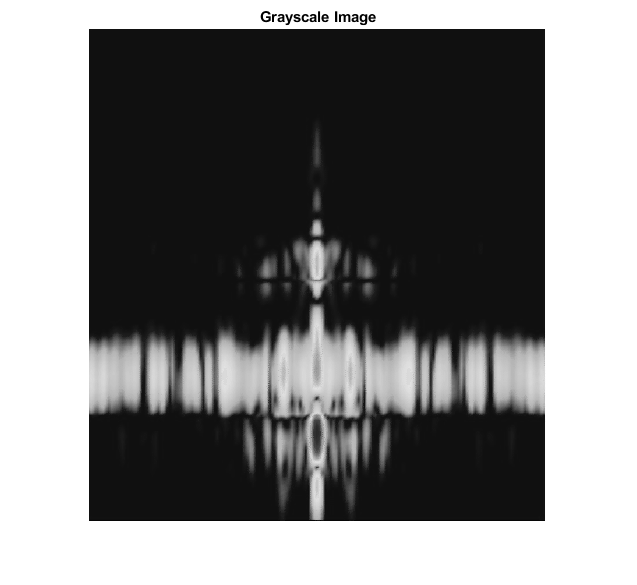

grayScale = rgb2gray(I);
% Display the resulting binary gradient mask
imshow(grayScale)
title('Grayscale Image')

## Step 3: Detect Edges with Sobel filter

To create a binary mask, functions `edge` and `Sobel` are used to calculate the threshold value. 

Display the resulting binary gradient mask.

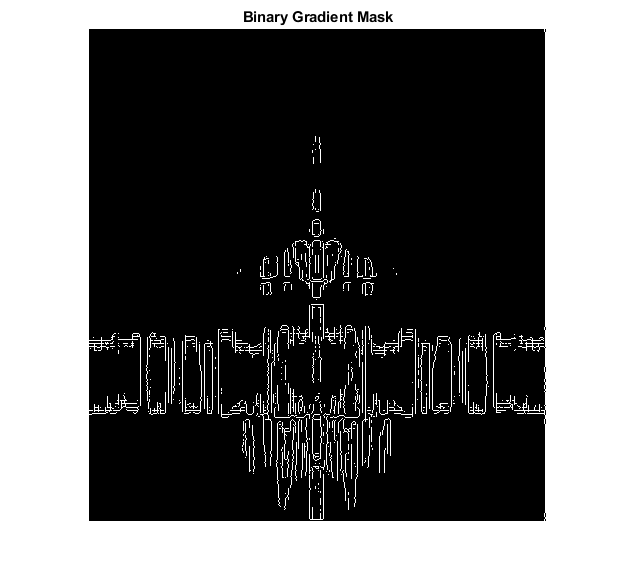

[~,threshold] = edge(grayScale,'sobel');
fudgeFactor = 0.5;
BWs = edge(grayScale,'sobel',threshold * fudgeFactor);

% Display the resulting binary gradient mask
imshow(BWs)
title('Binary Gradient Mask')

## Step 4: Dilate the Image

The binary mask shows the lines of high contrast in the image.

Dilate the binary gradient using the vertical structuring element followed by the horizontal structuring element.

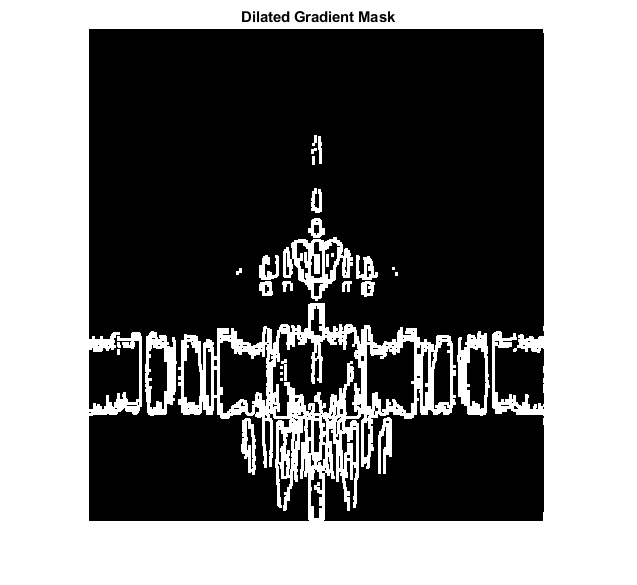

se90 = strel('line',3,90);
se0 = strel('line',3,0);

% Dilate the binary gradient mask
BWsdil = imdilate(BWs,[se90 se0]);
imshow(BWsdil)
title('Dilated Gradient Mask')

## Step 4: Fill the Interior Gaps

To fill the holes in the interior of the dilated gradient mask, use the `imfill` function.

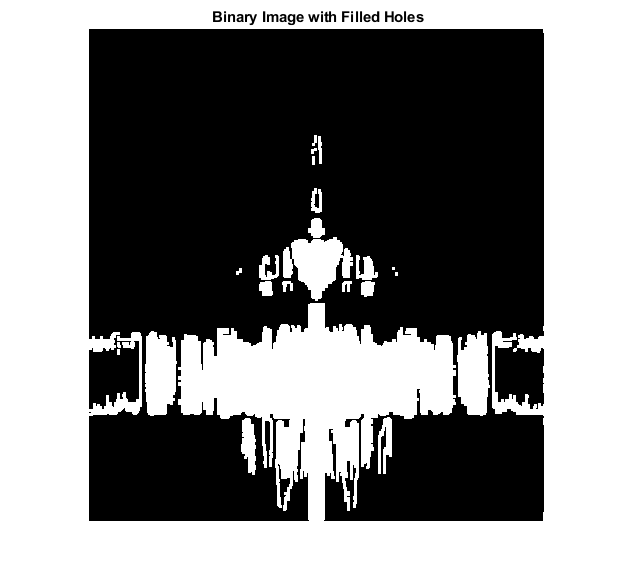

BWdfill = imfill(BWsdil,'holes');
imshow(BWdfill)
title('Binary Image with Filled Holes')

## Step 5: Remove Connected Objects on Border

The radar image has been successfully segmented, however it is not the only object that was found. Noise appears within the image, and can be removed using the `imclearborder` function.

Set the connectivity in the imclear function to 4.

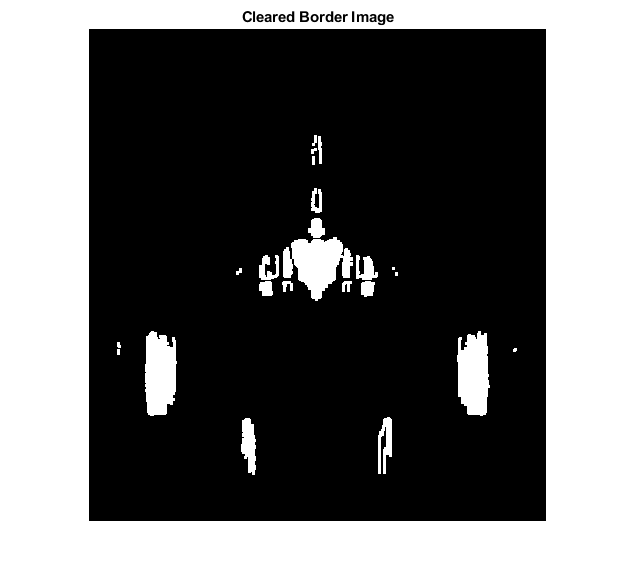

BWnobord = imclearborder(BWdfill,4);
imshow(BWnobord)
title('Cleared Border Image')

## Step 6: Smooth the Object

To make the segmented object look natural, smooth the object by eroding the image twice with a diamond structuring element. 

Create the diamond structuring element using the `strel` function.

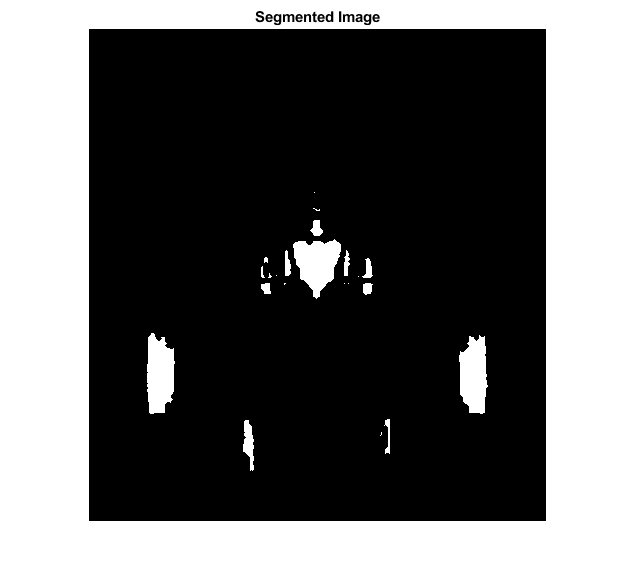

seD = strel('diamond',1);
BWfinal = imerode(BWnobord,seD);
BWfinal = imerode(BWfinal,seD);
imshow(BWfinal)
title('Segmented Image');

## Step 7: Visualize the Segmentation

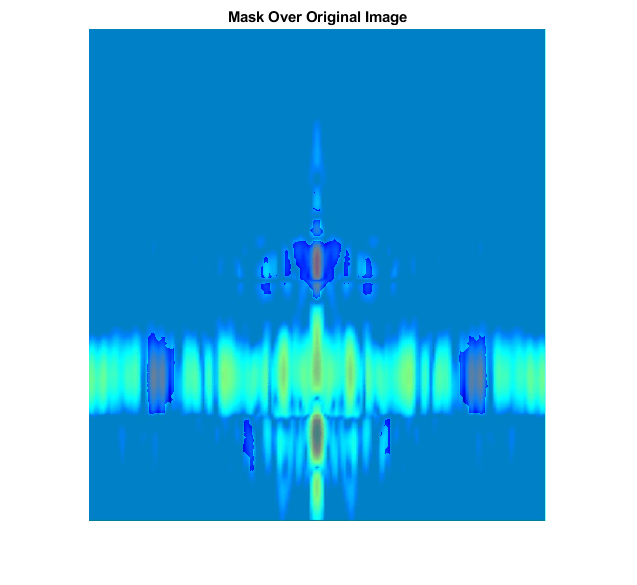

% Create categorical labels based on the image contents
stringArray = repmat("table", size(BWfinal));
stringArray(BWfinal) = "object";
categoricalSegmentation = categorical(stringArray);

% Fuse the categorical labels with the original image
mask = labeloverlay(I,categoricalSegmentation);
imshow(mask);
title('Mask Over Original Image')

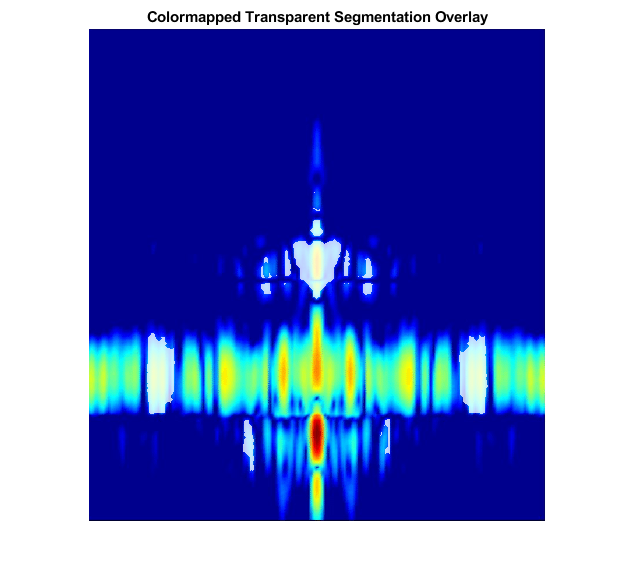

% Fuse the original image with only one label from the categorical
% segmentation
C = labeloverlay(I,categoricalSegmentation,'IncludedLabels',"object",'Colormap','white','Transparency',0.25);
imshow(C)
title('Colormapped Transparent Segmentation Overlay')

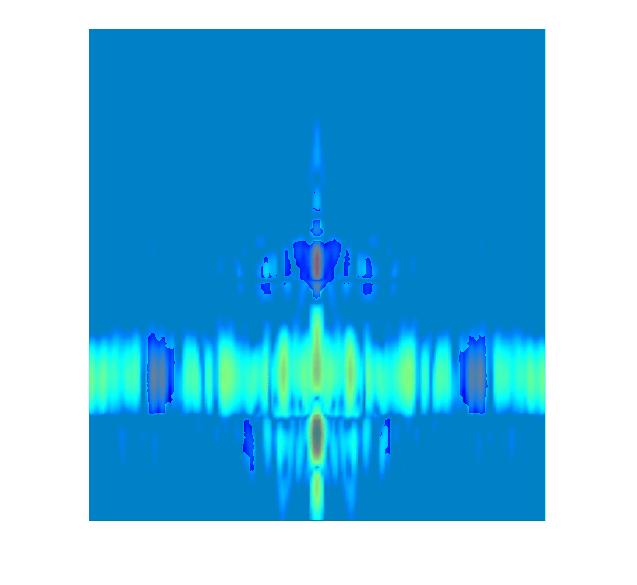

% Alternate Segmentation - Outlined
BWoutline = bwperim(BWfinal);

% Create categorical labels based on the image contents
stringArray2 = repmat("table", size(BWoutline));
stringArray2(BWoutline) = "object";
outlineCategoricalSegmentation = categorical(stringArray2);

% Fuse the categorical labels with the original image
outline_mask = labeloverlay(I,categoricalSegmentation);
imshow(outline_mask);

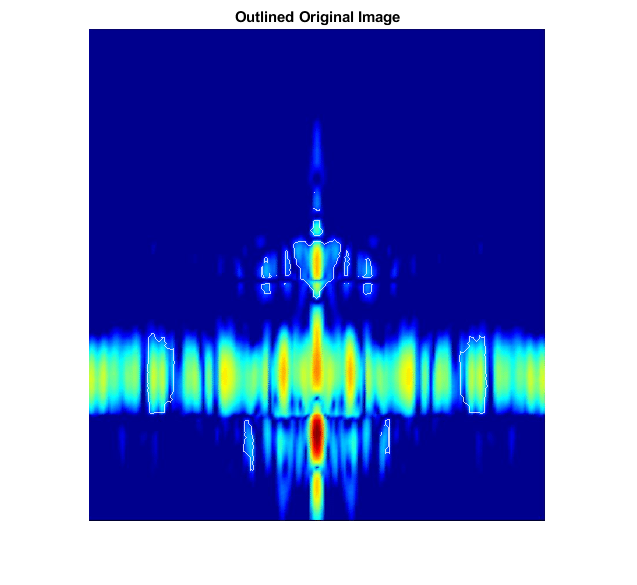


% Fuse the original image with only one label from the categorical
% segmentation
C = labeloverlay(I,outlineCategoricalSegmentation,'IncludedLabels',"object",'Colormap','white','Transparency',0.25);

% Display the Outlined Original Image
imshow(C)
title('Outlined Original Image')

## Reference

[1] [https://www.mathworks.com/help/images/detecting-a-cell-using-image-segmentation.html](https://www.mathworks.com/help/images/detecting-a-cell-using-image-segmentation.html)

[2] [https://www.mathworks.com/help/images/ref/labeloverlay.html](https://www.mathworks.com/help/images/ref/labeloverlay.html) 

***Note***: Requires Image Processing Toolbox in MATLAB for the functions to work.

[https://www.mathworks.com/matlabcentral/fileexchange/25157-image-segmentation-tutorial](https://www.mathworks.com/matlabcentral/fileexchange/25157-image-segmentation-tutorial)